# 二項分布と正規分布

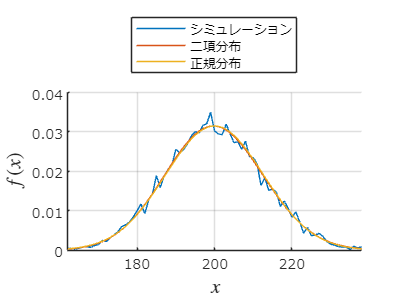

clear;clc;close all;

lambda=200;
n=1000;
M=10000;

p=lambda/n;
c=zeros(M,1);
for n1=1:M
    for n2=1:n
        if rand()<p
            c(n1)=c(n1)+1;
        end
    end
end

f=histcounts(c,0:n+1)/M;
x=0:n;
f_bin=binopdf(x,n,p);
f_norm=normpdf(x,lambda, sqrt(n*p*(1-p)));
figure;
grid on;hold on;set(gca,'fontname','メイリオ')
plot(x,[f;f_bin;f_norm]);
xlabel('$x$','Interpreter','latex','FontSize',12);
ylabel('$f(x)$','Interpreter','latex','FontSize',12);
legend({'シミュレーション','二項分布','正規分布'}, ...
    'Location','northoutside');
xlim(lambda+3*sqrt(n*p*(1-p))*[-1 1]);
exportgraphics(gcf,'fig_normal-bin.pdf');